# MCJC Learning Session LME - Part II: Step-by-Step Modeling Building

## Research Question and Experimental Design

Kelcy (I know, this was intentional!) is interested in ***"How brainstem excitability changes with increases in shoulder lifting load ", ***which can be nicely captured by

- Examining the ratio between the secondary (biceps, elbow) and primary (deltoid, shoulder) muscle activity, i.e., ***SPR***.,

- While the movement ('Lift') release is triggered by either a normal sound cue ('Go'), or by evoking a brainstem-mediated response to a loud, startling acoustic stimuli ('Startle').

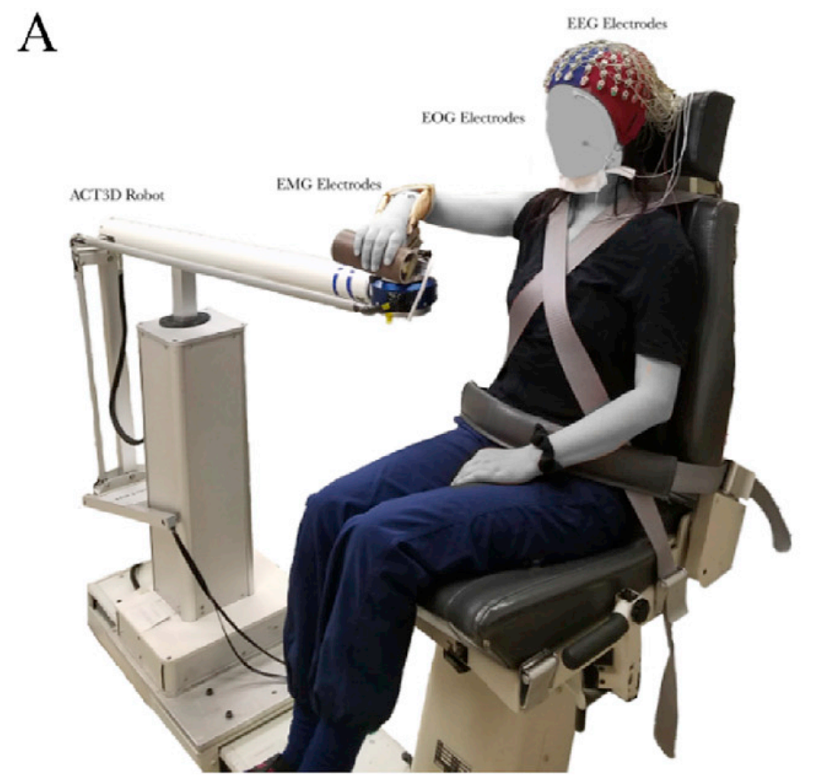

Her hypothesis is that ***"SPR will increase as shoulder load (or 'Lift') increases, however, at a faster rate in the 'Startle' condition compared to the 'Go' condition"***.

To test this hypothesis, she runs her experiment (n=10) designed as below:

- Depenent variable (outcome, observations): SPR

- Independent variables (predictors, factors): Lift x Sound

-     Lift: 5 levels (25 32 39 46 53% Sab) - continuous; could be categorical but would be a different model (getting estimates for each level)

-     Sound: 2 levels ('Go', 'Startle) - categorical

- Trials: repeated ~12 times per Lift level in 'Go' condition; ~ 6 times per Lift level in 'Startle'; nested within condition for each subject => However, for this exercise, we will only use data averaged per condition

So let's build a model to answer Kelcy's question!

## Step 0: Visualizing Your Data

Given the question, hypothesis, and experimental design, you'd already have some ideas for what kind of a statistical model (or tests) we'd run on our data. However, it is always better to first **examine the data by eye**, which should give us a better picture of what the results actually *look like* (e.g., differences, trends, distribution/variability), and thus would serve a great guideline for how we want to model them.

Let's load the data in Matlab.

clear; clc; % just cleaning up the workspace/memory before we start; a habit of many

% import csv data file (a format often used), to a Matlab table
Datatable = readtable('simulatedData.csv');

% Let's also define some variables that become handy to pull out the
% particular set of conditions we want later
sublist  = {'s01','s02','s03','s04','s05','s06','s07','s08','s09','s10'}; % in order of appearance
markerlist = {'o','+','*','x','square','diamond','^','v','pentagram','hexagram'};
liftlevels = [25, 32, 39, 46, 53];
sounds = {'Go','Startle'};

Now take a look at the table, in the Variable windows in Matlab. Some obervations:

- For most statistical packages (Matlab, R, SPSS), this is how you want to organize your data, with "long" columns, where one condition may be repeated many times in a column while another condition is varied in the other column. Although you could be better organizing more complicated data set (e.g., in many dimensions and factors) with [*structs*](https://www.mathworks.com/help/matlab/structures.html) or [*cells*](https://www.mathworks.com/help/matlab/cell-arrays.html) in Matlab, 'one observation (or data point) per one row' is usually the rule.

- As expected, we have 100 data points = 10 subjects x 5 lift levels x 2 sound conditions.

We will start by considering 'Lift' (loading level) as a continuous variable (which it is, and even with a physical/physiological meaning!), and assuming that the outcome SPR has some (e.g., linear) relationship to the 'Lift', which could however vary depending on other factors, e.g., sound condition, subjects, etc. Thus, we first choose to scatter plot Lift vs. SPR for all data, however, with different colors for sounds and different markers for subjects

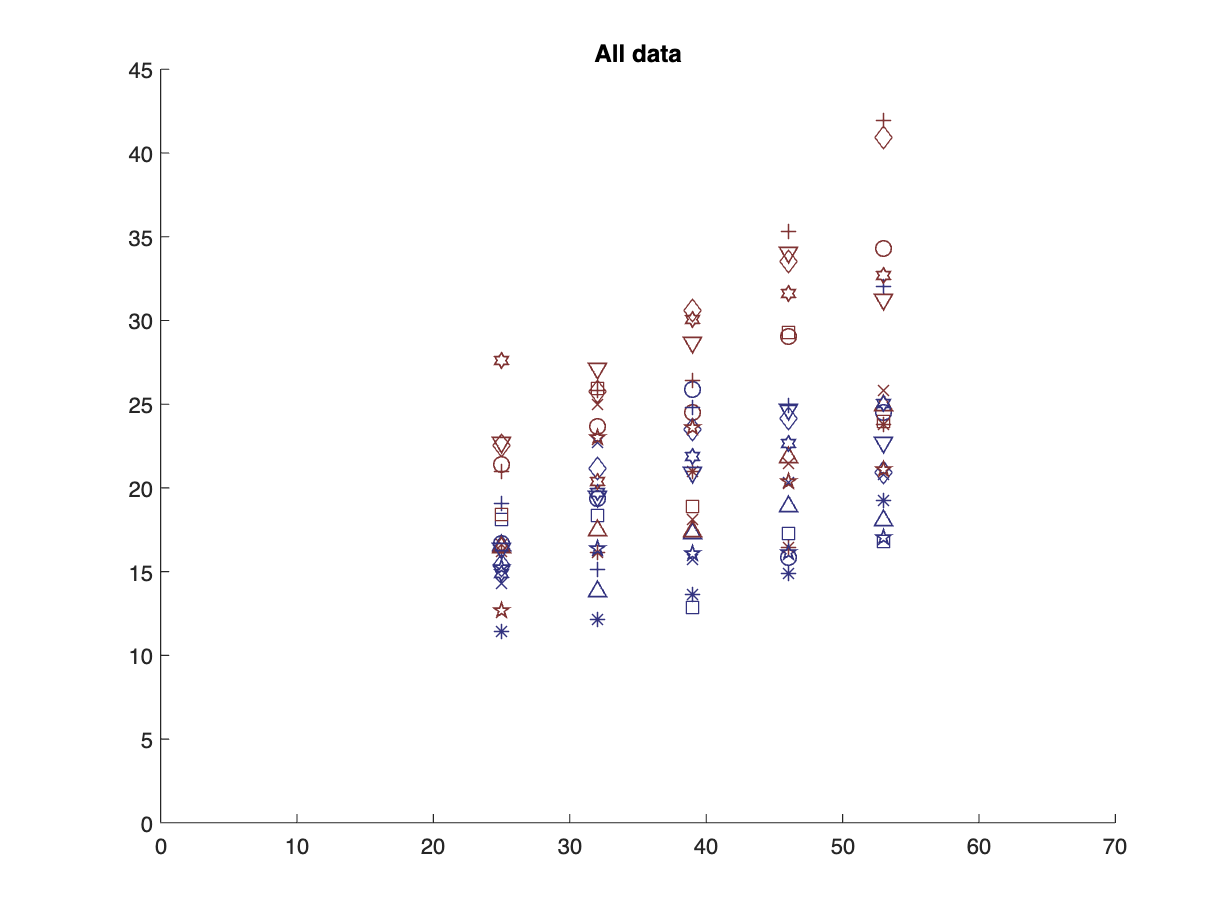

hold off; close all; % I don't know why I have to do this, but otherwise, output figures are displayed on top of what were there before, even if I plot after clearing all ouputs

color_dark = [0.2 0.2 0.5; 0.5 0.2 0.2]; % defining some color schemes to use consistently later
color_light = [0.5 0.5 0.75; 0.75 0.5 0.5];

for sub = 1:length(sublist) % plotting each subject for now
    for snd = 1:length(sounds)
        lift_temp = []; spr_temp = []; % place holder for temporary variables, cleared up each iteration of the for loop
        ind_cond = [];
        ind_cond = find(strcmp(Datatable.Sub,sublist(sub)) & strcmp(Datatable.Sound,sounds{snd}));
        lift_temp = Datatable.Lift(ind_cond);
        spr_temp = Datatable.SPR(ind_cond);
        scatter(lift_temp,spr_temp,50,markerlist{sub},'MarkerEdgeColor',color_dark(snd,:),'LineWidth',0.75)
        hold on
    end
    if sub == length(sublist)
        box off; ylim([0 45]); xlim([0 70])
        title('All data')
    end
end

#### Obervations:

- There obviously seems to be a linear trend with positive slope, i.e., increasing SPR as a function of increasing Lift levels.

- Can you tell the difference between sound conditions ('Go' in blue vs. 'Startle' in red)? How about across subjects?

Let's try a better way: Show each subject on a separate plot, however on the same scale (for better comparison across subjects), connecting the dots with lines, still with two sounds conditions on the same plot in different colors.

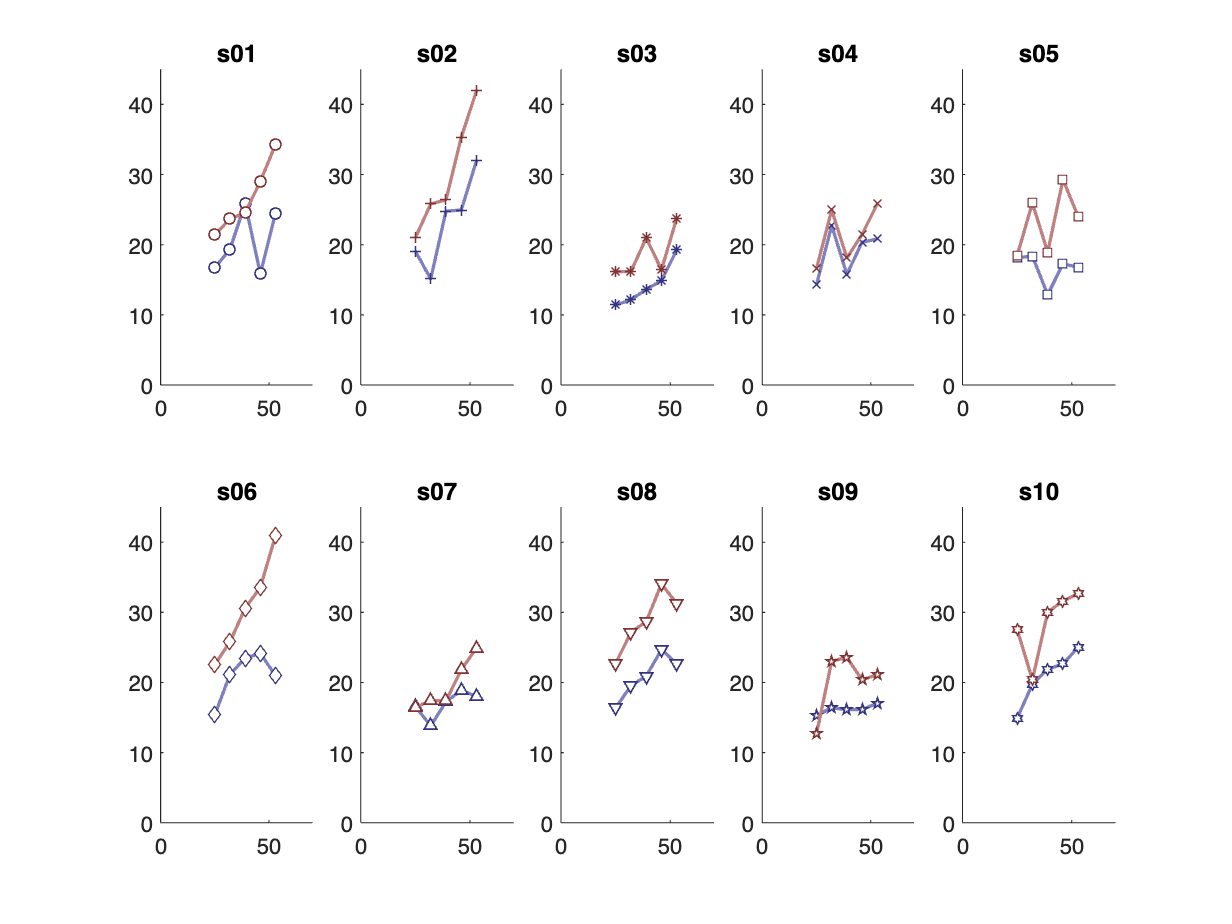

close all; hold off;
for sub = 1:length(sublist) % plotting each subject for now
    for snd = 1:length(sounds)
        lift_temp = []; spr_temp = []; % place holder for temporary variables, cleared up each iteration of the for loop
        ind_cond = [];
        ind_cond = find(strcmp(Datatable.Sub,sublist(sub)) & strcmp(Datatable.Sound,sounds{snd}));
        lift_temp = Datatable.Lift(ind_cond);
        spr_temp = Datatable.SPR(ind_cond);

        subplot(2,5,sub)
        plot(lift_temp,spr_temp,'Color',color_light(snd,:),'LineWidth',1.5)
        hold on
        scatter(lift_temp,spr_temp,25,markerlist{sub},'MarkerEdgeColor',color_dark(snd,:),'MarkerFaceColor','w','LineWidth',0.75)
        if snd == length(sounds)
            box off; ylim([0 45]); xlim([0 70])
            title(sublist(sub))
        end
    end
end

#### Observations:

- Better?

- What do you see, e.g., trends and differences? What about across subjects?

## Step 1: Linear vs. Mixed-effects model?

So let's start modeling. In general, we want to start from the simplest. But even before considering any "random-effects", let's first settle on "fixed-effects", also testing for whether we indeed need a "mixed-effects" model to begin with.

#### Linear model

To contruct any model and try fitting data, we go back to our question/hypothesis, which should remind us what we should be modeling. Our hypothesis, slightly modified using the terms for a linear model, was that: ***"SPR will increase as 'Lift' increases, however, with a greater slope in the 'Startle' condition compared to the 'Go' condition"***.

From this, it is evident that we want to at least model the slope, as well as the term that tells us about the difference in the slope between 'Go' and 'Startle'. What about intercept? How do we model the difference in the slope? How do we model using continous and/or categorical predictors? Without going into details, we will just answer these questions that by learning how to interpret the ouputs from a linear model.

Here is where we will start:

formula = 'SPR ~ Lift*Sound'; % this actually expands to 1 + Lift + Sound + Lift:Sound
% Note that there may be some minor syntax and/or configuration differences
% across programs (e.g., Matlab vs. R, or SPSS)

lm = fitlm(Datatable,formula) % intentionally ending without ';', to print results on screen

'fitlm' requires Statistics and Machine Learning Toolbox.

Interpreting the output:

- 'Intercept': Estimated intercept of the linear equation for 'Go' condition, that is, the value of SPR in 'Go' condition when load is zero => significant positive value, which is obvious from the look of our data

- 'Lift': Estimated slope of the linear equation for 'Go' condition => Also significant, positive number, as expected

- 'Sound_Startle': The ***DIFFERENCE in intercept for the 'Startle' condition, RELATIVE TO that of the 'Go' condition*** => not significant, although estimated to be slightly lower (negative difference)

- 'Lift:Sound_Startle': This is the interaction term, which models the ***DIFFERENCE in slope for the 'Startle' condition, RELATIVE TO that of the Go condition***. => not significant, although estimated to be slightly greater (i.e., positive difference).

From this, we can see that the terms that directly answers the hypothesis are 'Lift' and 'Lift:Sound_Startle'. The answer is yes for the first part of the hypothesis but no for the second part.

But let's examine the data, and think about your observations to these questions below:

- Do data for all subjects sit in rougly the same place/range?

- Are slope and intercept for all subjects look the same?

There are more proper ways to test the need for a mixed-effects model. But staying at the visual inspection level, we find that

- Yes, we do see quite a large range in data points across subjects. Subjects seem to sit on different places, or basically having different offsets, as well as maybe have slight differences in the slopes, if we were to fit a linear model. Such wide range in data points and/or different trends across subjects would yield large variance, and thus decrease the statistical power.

- This is where the ***Linear Mixed-Effects Models*** become handy, because 

- 1) It can model (or account for) that variance coming from some random distribution of data across subjects (i.e., random effect; required to be normal, but practically OK for the most part, as we are sampling only ~15 or less samples from the whole populations), and 

- 2) Let the main question of interest (i.e., fixed effect) be better captured at the population (or group) level, in this case, the outcome as a "linear" function of level (i.e., the slope), as well as the differene in this relationship (slope) between the sound condition (i.e., the interaction terms, which we will discuss later).

There are many other benefits of using LME, which we discussed briefly elsewhere. Let's try though, what we get by using a LME, however with the exact same fomula, which would illustrate the difference resulting from how LM vs. LME estimates the paratmers.

% update the formula
fixed_effects = 'Lift*Sound';
random_effects = [];
formula = ['SPR ~ ', fixed_effects];

lm % printing on screen again for comparison
lme0 = fitlme(Datatable,formula)

#### Quick observstion:

- Estimates are the same. The state are slightly different.

- This may result from OLS (ordinary least-squares) vs. ML (maximum likelihood) estimate methods; sometimes estimates could be different, but in most cases are quite similar.

## Step 2: Initial LME Model

So finally let's start building a LME model. Same here, we will start from the simplest.

- We will assume the subjects have different, normally distributed over the population mean, overall offset (or intercept) to begin with.

- We model this by a 'random slope' term, with 'Sub' being the random factor.

% update the formula
fixed_effects = 'Lift*Sound';
random_effects = '(1|Sub)';
formula = ['SPR ~ ', fixed_effects, ' + ', random_effects];

lme1 = fitlme(Datatable,formula)

#### Observations and interpretation:

- While the coefficient estimates for the fixed effects did not change at all, their stats changed (becoming "more" significant in general). The interaction term turned significant!

- The interpretation of the fixed effects stay the same. However, now we can consider them as estimates for the group, or population-level behaviors.

- Random 'Intercept' is then an stimate of the ***standard deviation of the intercept across 10 subjects***; we didn't yet model any covariation => Lower and upper 95% bounds indicate that this is a significant estimate, that there indeed was significane (assumedly normal) distribution across subjects in their intercept.

- FYI, 'Group: Error' basically is whatever the variance that the model could not explain

We can further look into details of the random Effects, which shows us the estimate for subject-specific intercepts, and their statistics. I believe the estimates indicate the difference to the group mean, i.e., the fixed Intercept term.

[B,Bnames,stats] = randomEffects(lme1);
stats

You can also look at some other measuers, such as MSE and R-squared (goodness-of-fit, however, in a OLS sense)

lme1.MSE
lme1.Rsquared.Adjusted

This is a pretty good fit already! Substantially improved from the lm model, which had Adjusted Rsquared of 0.428!

#### Visualization of results

Let's now take a look at what the model does. For illustration purpose, I will scatter plot the raw data for only selected subjects, but show model estimates in lines.

hold off; close all;
selected_subind = [2,3,5,7];
visualize(lme1,Datatable,selected_subind)

What do you see? Is this how you modeled it? Is this what you wanted to model?

## Step 2: Building on to More Complicated Models

However, we know from the look of our data, that 

- Subjects may also have different relationship, i.e., random slope for the 'Go' condition, however that is independent of the random intercept.

- We can go even further, assuming that there is a correlation between the random effect. For example, we could model that "those that have a large offset (either +/-) in intercept from the group mean may also have large difference in slope (+/-), also from the group mean. However, we will model that this subject-specific variation in slope is only around that of the 'Go' condition, and test, more conservatively in a sense, whether the difference in the slope between 'Go' vs. 'Slope' is the same.

We will test each cases, first, and later maybe combination of some.

### Case 1: Random slope for 'Go', independent of the random intercept

% update the formula
fixed_effects = '1 + Lift*Sound'; 
% 'Lift*Sound' term expands to 'Lift + Sound + Lift:Sound'
random_effects = '(1|Sub) + (-1+Lift|Sub)';

formula = ['SPR ~ ', fixed_effects, ' + ', random_effects];

lme1
lme21 = fitlme(Datatable,formula)

#### Observations:

- What happened to the fixed effects?

- What happened to the random effects?

hold off; close all;
selected_subind = [2,3,5,7];
visualize(lme21,Datatable,selected_subind)

### Case 2: Random slope for 'Go', covarying with the random intercept

% update the formula
fixed_effects = '1 + Lift*Sound'; 
random_effects = '(1 + Lift|Sub)';

formula = ['SPR ~ ', fixed_effects, ' + ', random_effects];
lme22 = fitlme(Datatable,formula)
hold off; close all;
selected_subind = [2,3,5,7];
visualize(lme22,Datatable,selected_subind)

### Case 3: Random intercept for both 'Go' and 'Startle' and random slope for 'Go', with full covariance structure

Well, why not model all other randome effects, EXCEPT, the interaction term which is of our main interest.

% update the formula
fixed_effects = '1 + Lift*Sound'; 
random_effects = '(1+Lift+Sound|Sub)';
formula = ['SPR ~ ', fixed_effects, ' + ', random_effects];

lme23 = fitlme(Datatable,formula)  %'CovariancePattern','FullCholesky(default)'; can be 'Diagonal', ... , 

hold off; close all;
selected_subind = [2,3,5,7];
visualize(lme23,Datatable,selected_subind)

Looks better. But how do we know if it really is better? How do we properly compare and test if it is better than the other? That is asking, whether adding the paramters helped explaining the model better, but still in a statistically significant way.

## Step 3: Model comparison

In Matlab, we use 'compare'. Below is the description from Matlab help; resources on model comparison in R can be found [here](https://joshuawiley.com/MonashHonoursStatistics/LMM_Comparison.html#comparing-models).

# compare

Class: [LinearMixedModel](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel-class.html)

Compare linear mixed-effects models

[expand all in page](about:blank<javascript:void(0);>)

## Syntax

[`results = compare(lme,altlme)`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#d124e253120)

[`results = compare(``___``,Name,Value)`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#d124e253191)

[`[results,siminfo] = compare(lme,altlme,'NSim',nsim)`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#d124e253219)

[`[results,siminfo] = compare(``___``,Name,Value)`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#d124e253257)

## Description

[`results`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-results) `= compare(`[`lme`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m_sep_shared-lme)`,`[`altlme`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-altlme)`)` returns the results of a [likelihood ratio test](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#bt2g4fp-2) that compares the linear mixed-effects models `lme` and `altlme`. Both models must use the same response vector in the fit and `lme` must be nested in `altlme` for a valid theoretical likelihood ratio test. Always input the smaller model first, and the larger model second.

`compare` tests the following null and alternate hypotheses:

*H*0: Observed response vector is generated by `lme`.

*H*1: Observed response vector is generated by model `altlme`.

It is recommended that you fit `lme` and `altlme` using the maximum likelihood (ML) method prior to model comparison. If you use the restricted maximum likelihood (REML) method, then both models must have the same fixed-effects design matrix.

To test for fixed effects, use `compare` with the [simulated likelihood ratio test](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#bt2g4fp-3) when `lme` and `altlme` are fit using ML or use the `fixedEffects`, `anova`, or `coefTest` methods.

[example](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#bt00xup-4)

[`results`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-results) `= compare(``___``,`[`Name,Value`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#namevaluepairarguments)`)` also returns the results of a likelihood ratio test that compares linear mixed-effects models `lme` and `altlme` with additional options specified by one or more `Name,Value` pair arguments.

For example, you can check if the first input model is nested in the second input model.

[example](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#bt00u7v-1)

`[`[`results`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-results)`,`[`siminfo`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-siminfo)`] = compare(`[`lme`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m_sep_shared-lme)`,`[`altlme`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-altlme)`,'NSim',`[`nsim`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-nsim)`)` returns the results of a simulated likelihood ratio test that compares linear mixed-effects models `lme` and `altlme`.

You can fit `lme` and `altlme` using ML or REML. Also, `lme` does not have to be nested in `altlme`. If you use the restricted maximum likelihood (REML) method to fit the models, then both models must have the same fixed-effects design matrix.

[example](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#bt07e3t-6)

`[`[`results`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-results)`,`[`siminfo`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#btvrk6m-siminfo)`] = compare(``___``,`[`Name,Value`](https://www.mathworks.com/help/releases/R2022b/stats/linearmixedmodel.compare.html#namevaluepairarguments)`)` also returns the results of a simulated likelihood ratio test that compares linear mixed-effects models `lme` and `altlme` with additional options specified by one or more `Name,Value` pair arguments.

For example, you can change the options for performing the simulated likelihood ratio test, or change the confidence level of the confidence interval for the *p*-value.

Our LME models so far

- In fact, are fitted with ML, instead of REML (restricted), method

- Have the same fixed effects

- With simpler model being nested within the more complex model

So let's try comparing lme1 and lme22

compare(lme1,lme21)

How about lme21 and lme22?

compare(lme21,lme22)

How about lme21 and lme23?

compare(lme21,lme23)

How about in terms of goodness-of-fit (R squared)?

lme21.Rsquared.Adjusted
lme23.Rsquared.Adjusted

## Step 4: Model Finalization

Lastly, we can also check whether even a more complex, but less conservative, model helps. That is, the full random effects including the interaction term.

% update the formula
fixed_effects = '1 + Lift*Sound'; 
random_effects = '(1+Lift*Sound|Sub)';
formula = ['SPR ~ ', fixed_effects, ' + ', random_effects];

lme3 = fitlme(Datatable,formula)
compare(lme23,lme3)

#### Fitting method: ML vs. REML

So we settle on the model. However, there is one more thing, the fitting method. We have been using ML for ease of comparison. However, in the end we want our estimates to be less biased (or unbiased).

% update the formula back to that of lme23
fixed_effects = '1 + Lift*Sound'; 
random_effects = '(1+Lift+Sound|Sub)';
formula = ['SPR ~ ', fixed_effects, ' + ', random_effects];

lme23
lme4 = fitlme(Datatable,formula,"FitMethod",'REML')
lme23.Rsquared.Adjusted
lme4.Rsquared.Adjusted

#### Observations

- What happened to the fixed effects, their estimates and stats?

- What happened to the random effects, their estimates and stats?

- What happened to goodness-of-fit measure?

function visualize(model,datatable,selected_subind)

sublist  = {'s01','s02','s03','s04','s05','s06','s07','s08','s09','s10'}; % in order of appearance
markerlist = {'o','+','*','x','square','diamond','^','v','pentagram','hexagram'};
liftlevels = [25, 32, 39, 46, 53];
sounds = {'Go','Startle'};

liftlevels_new = [0, liftlevels, 60];
% population results
Data_pop = table(repmat(sublist(1),14,1),repmat(liftlevels_new',2,1),[repmat(sounds(1),7,1);repmat(sounds(2),7,1)],'VariableNames',["Sub","Lift","Sound"]);
[ypred_pop,ypredCI_pop] = predict(model,Data_pop,'Conditional',false);

subplot(2,4,[1,2,5,6])
fill([liftlevels_new';flipud(liftlevels_new')],[ypredCI_pop(1:7,1);flipud(ypredCI_pop(1:7,2))],[0.5 0.5 0.75],'EdgeColor','none')
hold on
plot(liftlevels_new',ypred_pop(1:7,:),'Color',[0.2 0.2 0.5],'LineWidth',5)

fill([liftlevels_new';flipud(liftlevels_new')],[ypredCI_pop(8:14,1);flipud(ypredCI_pop(8:14,2))],[0.75 0.5 0.5],'EdgeColor','none')
plot(liftlevels_new',ypred_pop(8:14,:),'Color',[0.5 0.2 0.2],'LineWidth',5)
box off; ylim([0 45]); title('Population'); alpha(0.5)

for sub = 1:length(sublist) % individual, fitted/predicted
    Data_sub = table(repmat(sublist(sub),14,1),repmat(liftlevels_new',2,1),[repmat(sounds(1),7,1);repmat(sounds(2),7,1)],'VariableNames',["Sub","Lift","Sound"]);
    [ypred_sub,ypredCI_sub] = predict(model,Data_sub,'Conditional',true);
    plot(liftlevels_new',ypred_sub(1:7,:),'Color',[0.2 0.2 0.5],'LineWidth',0.25)
    scatter(liftlevels_new(end)',ypred_sub(7,:),'MarkerEdgeColor',[0.2 0.2 0.5],'LineWidth',0.5,'Marker',markerlist{sub}) % placing marker at the end
    plot(liftlevels_new',ypred_sub(8:14,:),'Color',[0.5 0.2 0.2],'LineWidth',0.25)
    scatter(liftlevels_new(end)',ypred_sub(14,:),'MarkerEdgeColor',[0.5 0.2 0.2],'LineWidth',0.5,'Marker',markerlist{sub})
end

% selected subjects     % selected_subind = [2,3,5,7]; 
subslot = [3,4,7,8];
for ss = 1:length(selected_subind) % individual, fitted/predicted
    subplot(2,4,subslot(ss))
    plot(liftlevels_new',ypred_pop(1:7,:),'Color',[0.2 0.2 0.5],'LineWidth',5)
    hold on
    plot(liftlevels_new',ypred_pop(8:14,:),'Color',[0.5 0.2 0.2],'LineWidth',5)

    Data_sub = table(repmat(sublist(selected_subind(ss)),14,1),repmat(liftlevels_new',2,1),[repmat(sounds(1),7,1);repmat(sounds(2),7,1)],'VariableNames',["Sub","Lift","Sound"]);
    ypred_sub = predict(model,Data_sub,'Conditional',true);
    plot(liftlevels_new',ypred_sub(1:7,:),'Color',[0.5 0.5 0.75],'LineWidth',1.5)
    plot(liftlevels_new',ypred_sub(8:14,:),'Color',[0.75 0.5 0.5],'LineWidth',1.5)

    for snd = 1:length(sounds)
        ind_cond = []; lev_temp = []; data_temp =[];
        ind_cond = find(strcmp(datatable.Sub, sublist(selected_subind(ss))) & ...
            strcmp(datatable.Sound,sounds{snd}));
        lev_temp = datatable.Lift(ind_cond);
        data_temp = datatable.SPR(ind_cond);
        if snd==1
            scatter(lev_temp,data_temp,markerlist{selected_subind(ss)},'MarkerEdgeColor',[0.2 0.2 0.5],'LineWidth',0.75)
        elseif snd==2
            scatter(lev_temp,data_temp,markerlist{selected_subind(ss)},'MarkerEdgeColor',[0.5 0.2 0.2],'LineWidth',0.75)
            box off; ylim([0 45]); title(['Sub' sublist(selected_subind(ss))])
        end
    end
end
end